%% Initialisierung
clear; % Löscht Variablen im Workspace
clc; % Löscht die Befehlszeile

% ---- Tiefpass-Teil ----
% Gegebene Werte für Tiefpass       R nach E12, C nach E6
R1_Tiefpass = 12e3; % Ohm
R2_Tiefpass = 150e3; % Ohm
R3_Tiefpass = 33e3; % Ohm
C1_Tiefpass = 470e-12; % Farad
C2_Tiefpass = 220e-12; % Farad
C3_Tiefpass = 6.8e-12; % Farad
zeta_Tiefpass = 0.707; % Angenommener Wert für das Dämpfungsverhältnis

% Symbolische Variable s definieren
s = tf('s');

% Cut-off Frequenzen für Tiefpass berechnen
fc1_Tiefpass = 1 / (2 * pi * R1_Tiefpass * C1_Tiefpass);
fc2_Tiefpass = 1 / (2 * pi * sqrt(R2_Tiefpass * R3_Tiefpass * C2_Tiefpass * C3_Tiefpass));

disp(['fc1_Tiefpass: ', num2str(fc1_Tiefpass), ' Hz']);

fc1_Tiefpass: 28218.9615 Hz


disp(['fc2_Tiefpass: ', num2str(fc2_Tiefpass), ' Hz']);

fc2_Tiefpass: 58485.9752 Hz



fc1TP_rad = 2*pi*fc1_Tiefpass;
fc2TP_rad = 2*pi*fc2_Tiefpass;

% Tiefpass-Übertragungsfunktionen definieren
% RC Tiefpass
T_RC_Tiefpass = 1 / (1 + s / (2 * pi * fc1_Tiefpass));
% Sallen-Key Tiefpass  ohne cheby-Verhalten
T_SK_Tiefpass = (2 * pi * fc2_Tiefpass)^2 / (s^2 + s * (2 * pi * fc2_Tiefpass) * 2 * zeta_Tiefpass + (2 * pi * fc2_Tiefpass)^2);

% Gesamtübertragungsfunktion für Tiefpass berechnen
Gesamt_Tiefpass = T_RC_Tiefpass * T_SK_Tiefpass;

% ---- Hochpass-Teil ----
% Gegebene Werte für Hochpass       R nach E12, C nach E6
R1_Hochpass = 5.6e3; % Ohm
R2_Hochpass = 10e3; % Ohm
R3_Hochpass = 270e3; % Ohm
C1_Hochpass = 330e-12; % Farad
C2_Hochpass = 68e-12; % Farad
C3_Hochpass = 68e-12; % Farad
zeta_Hochpass = 0.707; % Angenommener Wert für das Dämpfungsverhältnis

% Cut-off Frequenzen für Hochpass berechnen
fc1_Hochpass = 1 / (2 * pi * R1_Hochpass * C1_Hochpass);
fc2_Hochpass = 1 / (2 * pi * sqrt(R2_Hochpass * R3_Hochpass * C2_Hochpass * C3_Hochpass));

disp(['fc1_Hochpass: ', num2str(fc1_Hochpass), ' Hz']);

fc1_Hochpass: 86122.8047 Hz


disp(['fc2_Hochpass: ', num2str(fc2_Hochpass), ' Hz']);

fc2_Hochpass: 45043.2104 Hz



fc1HP_rad = 2*pi*fc1_Hochpass;
fc2HP_rad = 2*pi*fc2_Hochpass;

% Hochpass-Übertragungsfunktionen definieren
% RC Hochpass
H_RC_Hochpass = s / (s + 2 * pi * fc1_Hochpass);
% Sallen-Key Hochpass ohne cheby-Verhalten
H_SK_Hochpass = s^2 / (s^2 + s * 2 * pi * fc2_Hochpass * 2 * zeta_Hochpass + (2 * pi * fc2_Hochpass)^2);

% Gesamtübertragungsfunktion für Hochpass berechnen
Gesamt_Hochpass = H_RC_Hochpass * H_SK_Hochpass;

% ---- Bandpass-Teil ----
% Berechnung der Gesamtübertragungsfunktion für den Bandpass
Gesamt_Bandpass = Gesamt_Tiefpass * Gesamt_Hochpass;

% Übertragungsfunktionen anzeigen
disp('Gesamtübertragungsfunktion Bandpass:');

Gesamtübertragungsfunktion Bandpass:


disp(Gesamt_Bandpass);

  tf with properties:

       Numerator: {[0 0 0 2.3943e+16 0 0 0]}
     Denominator: {[1 1.6382e+06 1.1798e+12 4.8786e+17 1.2013e+23 1.6949e+28 1.0378e+33]}
        Variable: 's'
         IODelay: 0
      InputDelay: 0
     OutputDelay: 0
       InputName: {''}
       InputUnit: {''}
      InputGroup: [1×1 struct]
      OutputName: {''}
      OutputUnit: {''}
     OutputGroup: [1×1 struct]
           Notes: [0×1 string]
        UserData: []
            Name: ''
              Ts: 0
        TimeUnit: 'seconds'
    SamplingGrid: [1×1 struct]



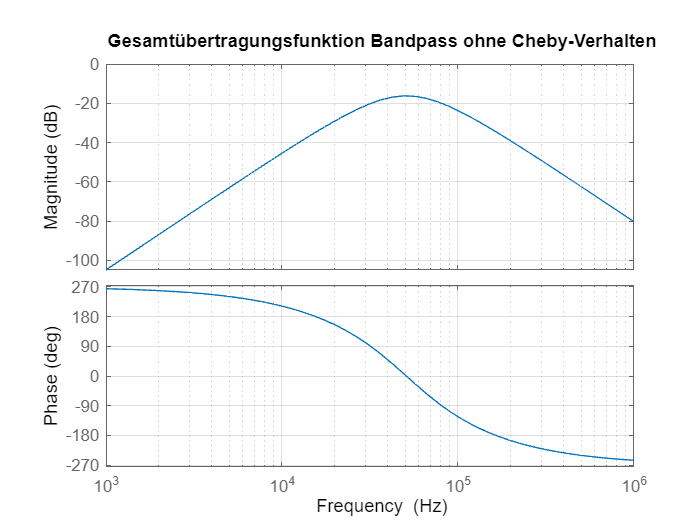


% Bode-Diagramm für Bandpass zeichnen
figure;
BodeDgrBPges = bodeplot(Gesamt_Bandpass);
title('Gesamtübertragungsfunktion Bandpass ohne Cheby-Verhalten');
opt = getoptions(BodeDgrBPges);
opt.Grid = 'on';
opt.FreqUnits = 'Hz';
setoptions(BodeDgrBPges,opt);

Bode TP 1ste Ordnung

[Ziel_Coeff_Za_TP1,Ziel_Coeff_Ne_TP1] = cheby1(1,3,fc1TP_rad,'low', 's');
Ziel_Coeff_Ne_TP1 = Ziel_Coeff_Ne_TP1 / Ziel_Coeff_Za_TP1(2);
Ziel_Coeff_Za_TP1 = Ziel_Coeff_Za_TP1 / Ziel_Coeff_Za_TP1(2);

f_von_p_TP1 = tf(Ziel_Coeff_Za_TP1,Ziel_Coeff_Ne_TP1)

f_von_p_TP1 =
 
         1
  ---------------
  5.627e-06 s + 1
 
Continuous-time transfer function.



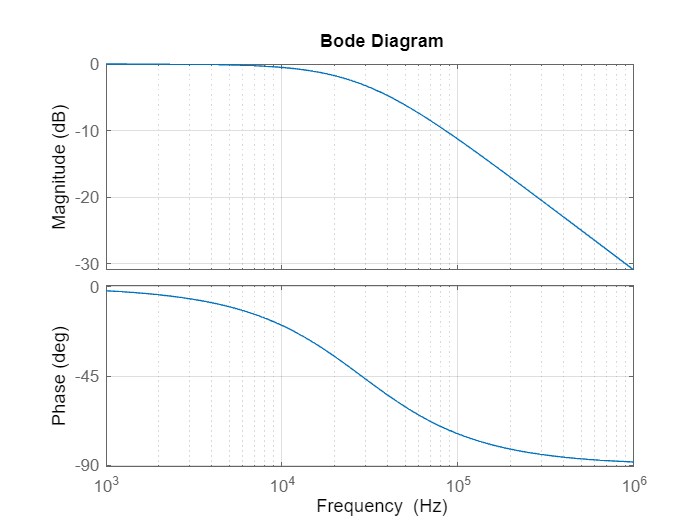


BodeDgrTP1 = bodeplot(f_von_p_TP1); 
opt = getoptions(BodeDgrTP1);
opt.Grid = 'on';
opt.FreqUnits = 'Hz';
setoptions(BodeDgrTP1,opt);

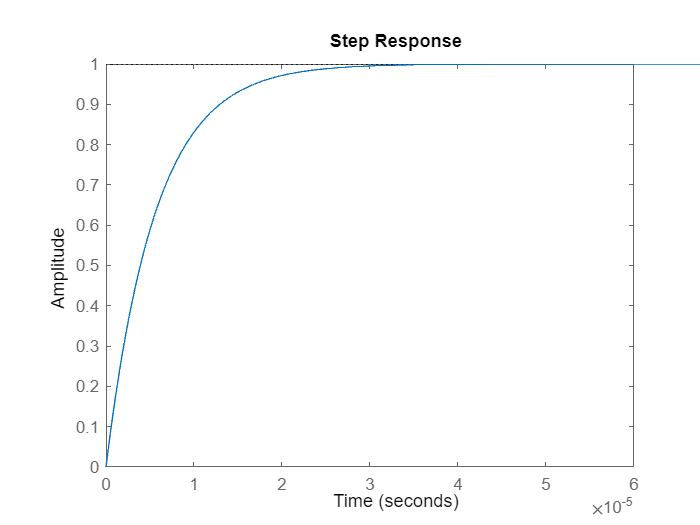


step(f_von_p_TP1);

Bode TP 2er Ordnung

[Ziel_Coeff_Za_TP2,Ziel_Coeff_Ne_TP2] = cheby1(2,3,fc2TP_rad,'low', 's');
Ziel_Coeff_Ne_TP2 = Ziel_Coeff_Ne_TP2 / Ziel_Coeff_Ne_TP2(3);
Ziel_Coeff_Za_TP2 = Ziel_Coeff_Za_TP2 / Ziel_Coeff_Za_TP2(3);

f_von_p_TP2 = tf(Ziel_Coeff_Za_TP2,Ziel_Coeff_Ne_TP2)

f_von_p_TP2 =
 
                 1
  -------------------------------
  1.046e-11 s^2 + 2.479e-06 s + 1
 
Continuous-time transfer function.



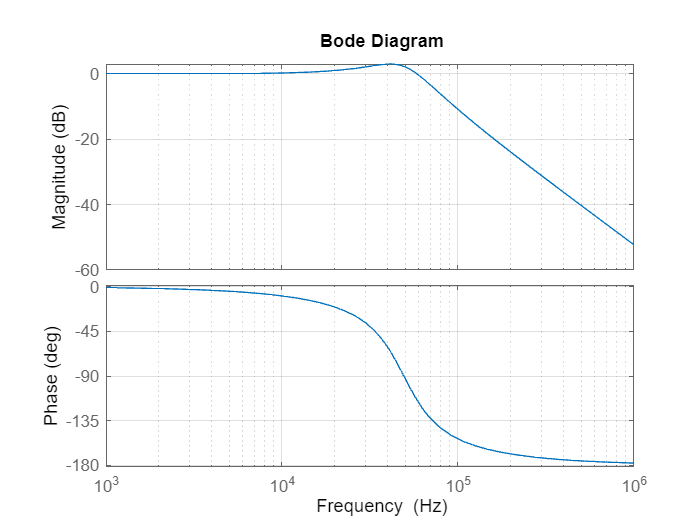


BodeDgrTP2 = bodeplot(f_von_p_TP2); 
opt = getoptions(BodeDgrTP2);
opt.Grid = 'on';
opt.FreqUnits = 'Hz';
setoptions(BodeDgrTP2,opt);

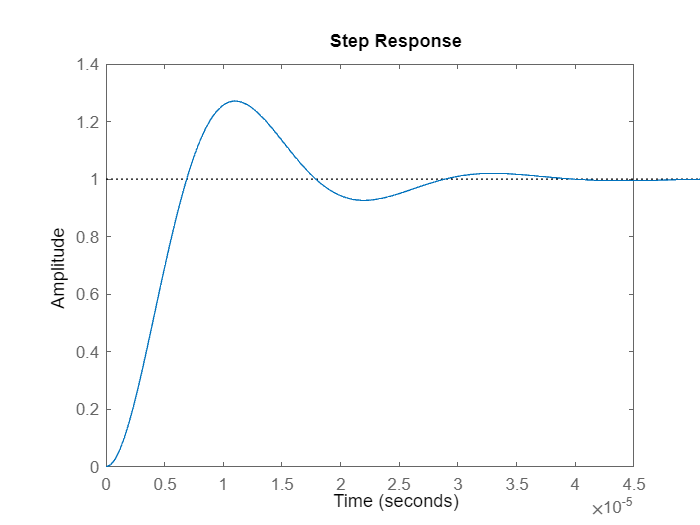


step(f_von_p_TP2);

TP3

[Ziel_Coeff_Za_TP3,Ziel_Coeff_Ne_TP3] = cheby1(3,3,355301,'low', 's'); %56548 Hz
Ziel_Coeff_Ne_TP3 = Ziel_Coeff_Ne_TP3 / Ziel_Coeff_Za_TP3(4);
Ziel_Coeff_Za_TP3 = Ziel_Coeff_Za_TP3 / Ziel_Coeff_Za_TP3(4);

f_von_p_TP3 = tf(Ziel_Coeff_Za_TP3,Ziel_Coeff_Ne_TP3)

f_von_p_TP3 =
 
                         1
  -----------------------------------------------
  8.897e-17 s^3 + 1.888e-11 s^2 + 1.043e-05 s + 1
 
Continuous-time transfer function.



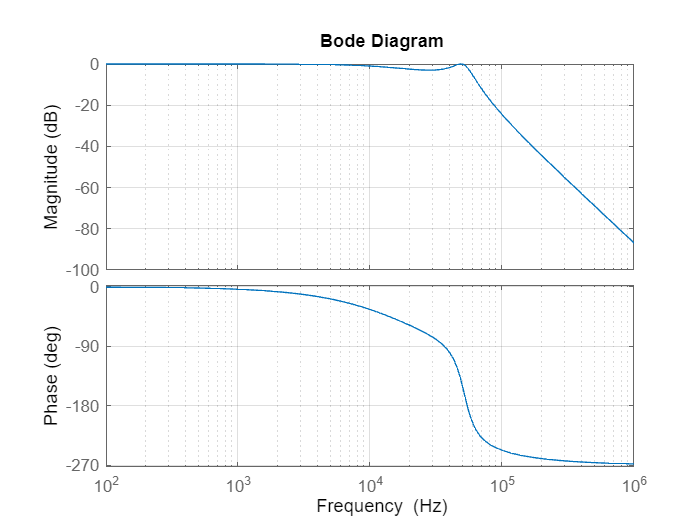


BodeDgrTP3 = bodeplot(f_von_p_TP3); 
opt = getoptions(BodeDgrTP3);
opt.Grid = 'on';
opt.FreqUnits = 'Hz';
setoptions(BodeDgrTP3,opt);

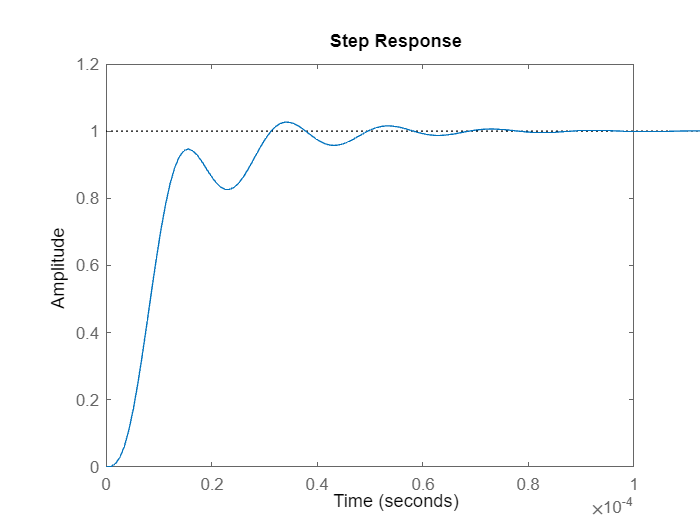


step(f_von_p_TP3);

Bode HP 1ste Ordnung

[Ziel_Coeff_Zae_HP1,Ziel_Coeff_Ne_HP1] = cheby1(1,3,fc1HP_rad,'high', 's');
Ziel_Coeff_Zae_HP1 = Ziel_Coeff_Zae_HP1 / Ziel_Coeff_Ne_HP1(2); 
Ziel_Coeff_Ne_HP1 = Ziel_Coeff_Ne_HP1 / Ziel_Coeff_Ne_HP1(2);

f_von_p_HP1 = tf(Ziel_Coeff_Zae_HP1,Ziel_Coeff_Ne_HP1)

f_von_p_HP1 =
 
    1.852e-06 s
  ---------------
  1.852e-06 s + 1
 
Continuous-time transfer function.



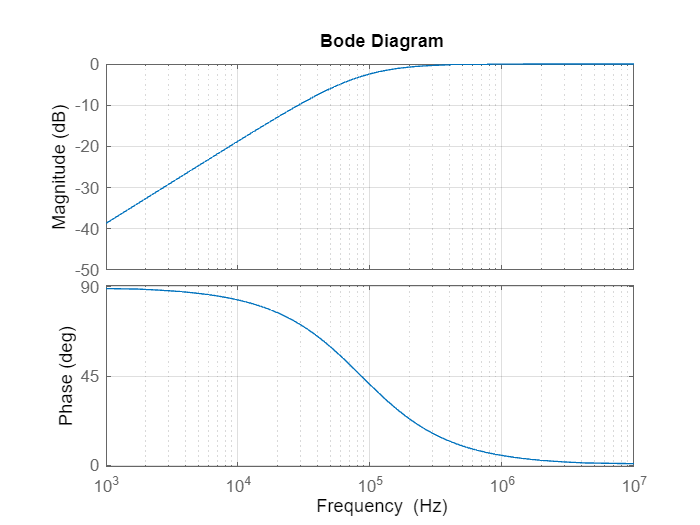


BodeDgrHP1 = bodeplot(f_von_p_HP1); 
opt = getoptions(BodeDgrHP1);
opt.Grid = 'on';
opt.FreqUnits = 'Hz';
setoptions(BodeDgrHP1,opt);

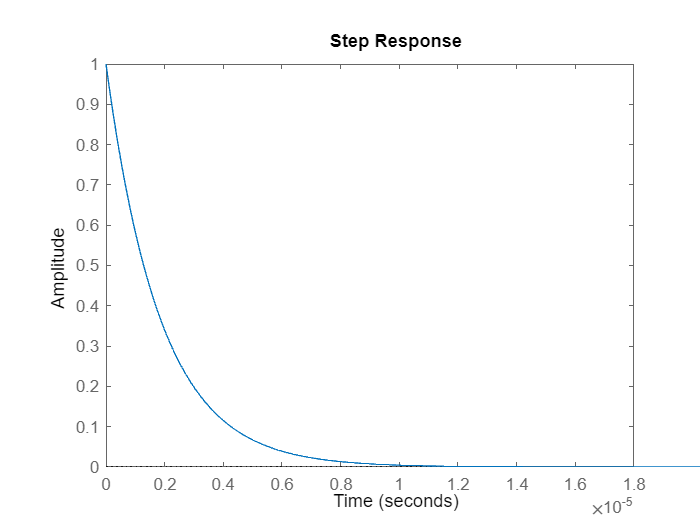


step(f_von_p_HP1); %Einschaltverhalten

Bode HP 2er Ordnung 

[Ziel_Coeff_Zae_HP2, Ziel_Coeff_Ne_HP2] = cheby1(2,3,fc2HP_rad,'high', 's');
Ziel_Coeff_Zae_HP2 = Ziel_Coeff_Zae_HP2 / Ziel_Coeff_Ne_HP2(3);
Ziel_Coeff_Ne_HP2 = Ziel_Coeff_Ne_HP2 / Ziel_Coeff_Ne_HP2(3);
f_von_p_HP2 = tf(Ziel_Coeff_Zae_HP2,Ziel_Coeff_Ne_HP2)

f_von_p_HP2 =
 
           6.257e-12 s^2
  -------------------------------
  8.839e-12 s^2 + 2.279e-06 s + 1
 
Continuous-time transfer function.



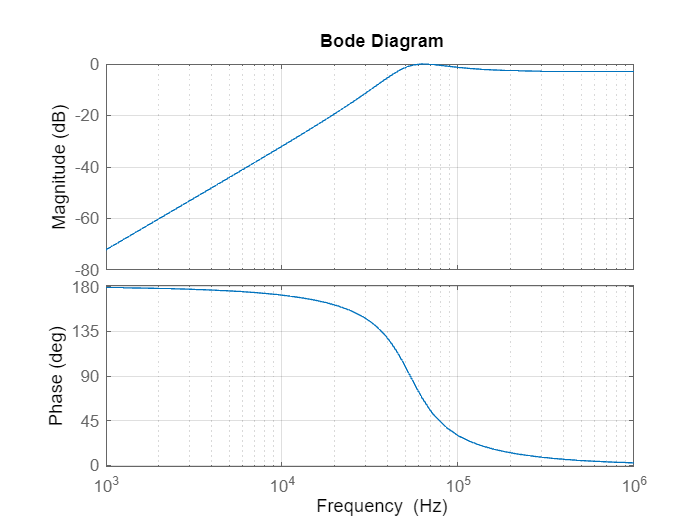


BodeDgrHP2 = bodeplot(f_von_p_HP2);
opt = getoptions(BodeDgrHP2);
opt.Grid = 'on';
opt.FreqUnits = 'Hz';
setoptions(BodeDgrHP2,opt); 

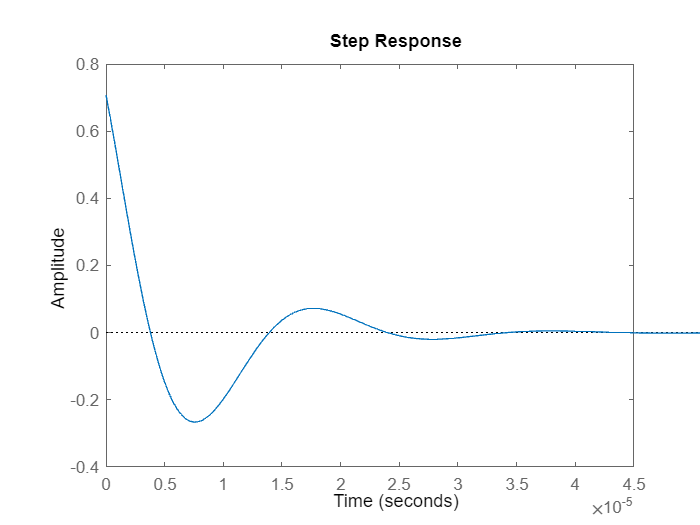


step(f_von_p_HP2);

HP3

[Ziel_Coeff_Zae_HP3, Ziel_Coeff_Ne_HP3] = cheby1(3,3,279551,'high', 's'); % 44492 Hz
Ziel_Coeff_Zae_HP3 = Ziel_Coeff_Zae_HP3 / Ziel_Coeff_Ne_HP3(4);
Ziel_Coeff_Ne_HP3 = Ziel_Coeff_Ne_HP3 / Ziel_Coeff_Ne_HP3(4);
f_von_p_HP3 = tf(Ziel_Coeff_Zae_HP3,Ziel_Coeff_Ne_HP3)

f_von_p_HP3 =
 
                   1.147e-17 s^3
  -----------------------------------------------
  1.147e-17 s^3 + 1.188e-11 s^2 + 2.136e-06 s + 1
 
Continuous-time transfer function.



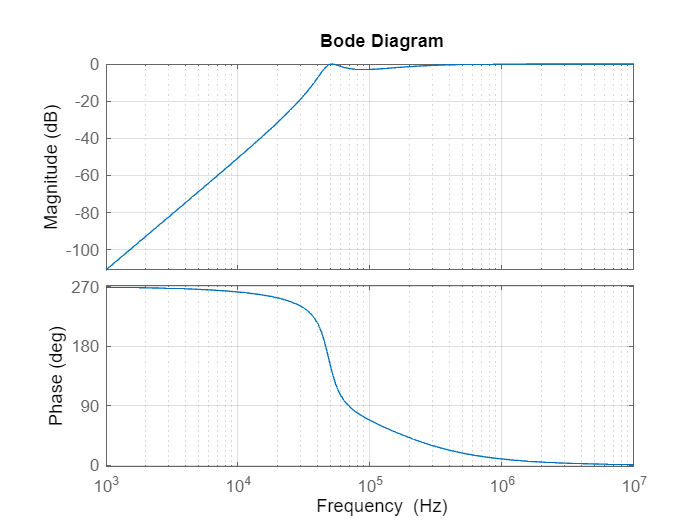


BodeDgrHP3 = bodeplot(f_von_p_HP3); 
opt = getoptions(BodeDgrHP3);
opt.Grid = 'on';
opt.FreqUnits = 'Hz';
setoptions(BodeDgrHP3,opt);

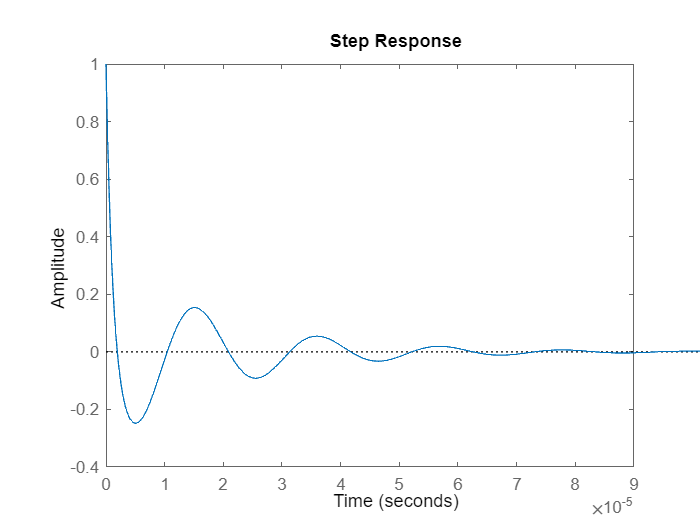


step(f_von_p_HP3);

Bode TP*HP

BP = f_von_p_TP3*f_von_p_HP3

BP =
 
                                                      
                                         1.147e-17 s^3
                                                      
  --------------------------------------------------------------------------------------------
                                                                                              
  1.021e-33 s^6 + 1.273e-27 s^5 + 5.339e-22 s^4 + 2.646e-16 s^3 + 5.303e-11 s^2 + 1.256e-05 s 
                                                                                              
                                                                                           + 1
                                                                                              
 
Continuous-time transfer function.



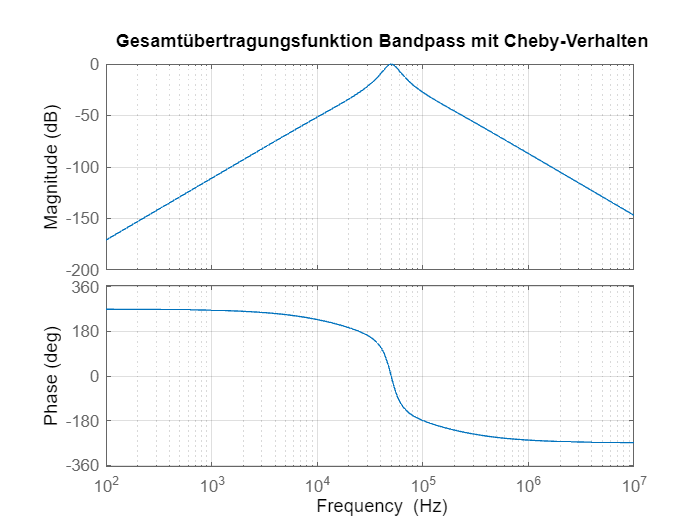

BodeDgrBP = bodeplot(BP);
title('Gesamtübertragungsfunktion Bandpass mit Cheby-Verhalten');
opt = getoptions(BodeDgrBP);
opt.Grid = 'on';
opt.FreqUnits = 'Hz';
setoptions(BodeDgrBP,opt);

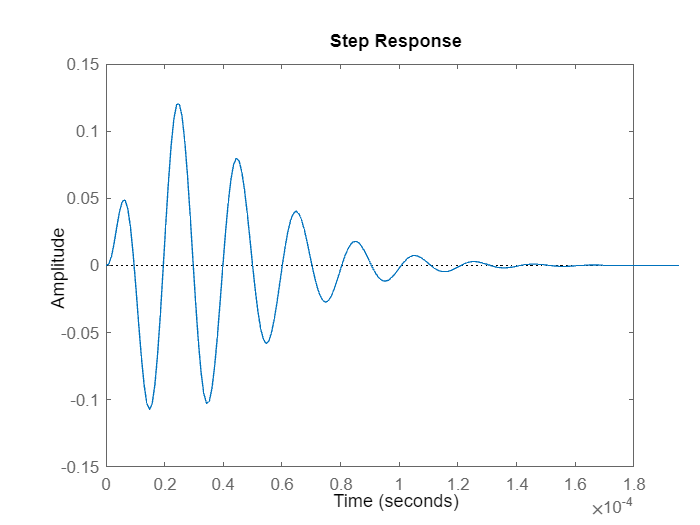

step(BP);